[head,r]=fastaread('beta_covid.txt')

head = 'NC_045512.2 Severe acute respiratory syndrome coronavirus 2 isolate Wuhan-Hu-1, complete genome'

r = 'ATTAAAGGTTTATACCTTCCCAGGTAACAAACCAACCAACTTTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGGCTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCGTCTATCTTCTGCAGGCTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTTTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGTCTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGCGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCGGATGCTCGAACTGCACCTCATGGTCATGTTATGGTTGAGCTGGTAGCAGAACTCGAAGGCATTCAGTACGGTCGTAGTGGTGAGACACTTGGTGTCCTTGTCCCTCATGTGGGCGAAATACCAGTGGCTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCCGATCTAAAGTCATTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTTACCCGTGAACTCATGCGTGAGCTTAACGGAGGGGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCACGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAGAGGGGTGTATACTGCTGCCGTGAACATGAGCATGAAATTGCTTGGTACACGGAAC

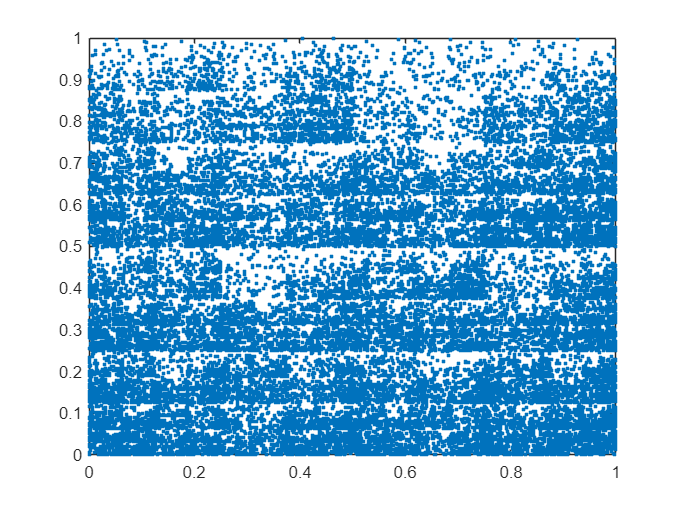

syms x1 y1 A G C T
x0=0.5;
y0=0.5;
xa=0;
xc=0;
xg=1;
xt=1;
ya=0;
yc=1;
yt=0;
yg=1;

X0=[x0,y0];
XA=[xa ya];
XT=[xt yt];
XC=[xc yc];
XG=[xg yg];
locx=[];
locy=[];

for i =1
  if r(1)==A
        x(i)=0.5*(xa+x0);
        y(i)=0.5*(ya+y0);
    elseif r(1)==T
        x(i)=0.5*(xt+x0);
         y(i)=0.5*(yt+y0);
    elseif r(1)==C
         x(i)=0.5*(xc+x0);
        y(i)=0.5*(yc+y0);
    else 
         x(i)=0.5*(xg+x0);
         y(i)=0.5*(yg+y0);
    end
    locx=[x(i) locx];
    locy=[y(i) locy];
end
for i=2:length(r)
    if r(i)==A
        x(i)=0.5*(xa+x(i-1));
        y(i)=0.5*(ya+y(i-1));
    elseif r(i)==T
         x(i)=0.5*(xt+x(i-1));
         y(i)=0.5*(yt+y(i-1));
    elseif r(i)==C
         x(i)=0.5*(xc+x(i-1));
         y(i)=0.5*(yc+y(i-1));
    else 
        x(i)=0.5*(xg+x(i-1));
         y(i)=0.5*(yg+y(i-1));
    end
     locx=[x(i) locx];
    locy=[y(i) locy];
end
    
%end

plot(locx,locy,'.')

%https://www.ncbi.nlm.nih.gov/nuccore/NC_045512.2?report=fasta
%Severe acute respiratory syndrome coronavirus 2 isolate Wuhan-Hu-1, complete genome

[x,y] = GCSkew(r(1:10000));
[val,idx] = max(y)

val = 109

idx = 19

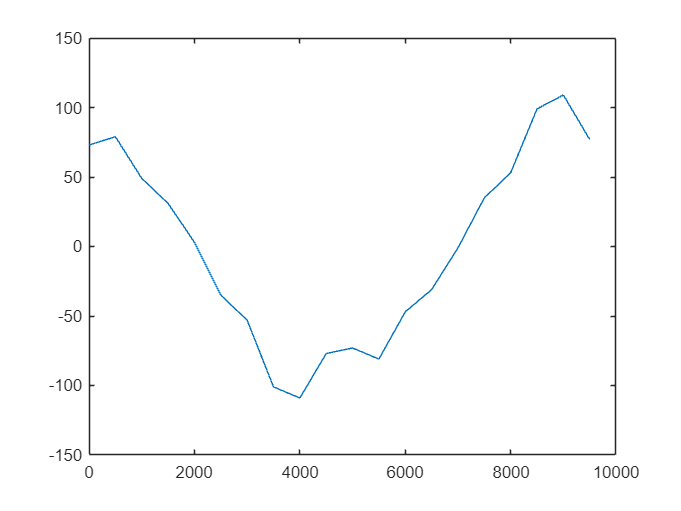

plot(x,y)

o= kmerPositions(5,r)

o =   Map with properties:

        Count: 512
      KeyType: char
    ValueType: any


function [pp] = kmerPositions(k,seq)

kmerPosition = containers.Map;
for i=1:length(seq)-k+1
kmer = seq(i:i+k-1);

 if(kmerPosition.isKey(kmer))
kmerPosition(kmer) =sort( [kmerPosition(kmer) i] );
else
kmerPosition(kmer)=i;
end
end

keysss = kmerPosition.keys;
positions = kmerPosition.values;

pairPosition = containers.Map;
for i=1:kmerPosition.Count
kmer = keysss{i};
poslist = positions{i};

 temp=strrep(strrep(strrep(strrep( kmer(end:-1:1) ,'A','*'),'C','.'),'T','A'),'G','C');
krev = strrep(strrep(temp,'*','T'),'.','G');

 if( convertCharsToStrings(kmer) < convertCharsToStrings(krev))
if(kmerPosition.isKey(krev))
pairPosition(kmer) = sort([poslist, kmerPosition(krev)] );
else
pairPosition(krev) = sort(poslist);
end
elseif(convertCharsToStrings(krev) < convertCharsToStrings(kmer))
if(kmerPosition.isKey(krev))
pairPosition(krev) = sort([kmerPosition(krev),poslist]);
else
pairPosition(krev) = sort(poslist);
end
else
pairPosition(kmer)=poslist;
end
pp = pairPosition;

end

end
function [clumpps,boxclumps] = findClumps(string, k , L , t)

clumps=[];
bclumps =[];

 for i=1:length(string)-L
start = i;
END = i+L-1;
box = string(start:END);
kmerpositions = kmerPositions(k,box);
kmers = kmerpositions.keys;
positions = kmerpositions.values;
for j=1:kmerpositions.Count
kmer = kmers{j};
poslist = positions{j};
for k_ = 1:length(poslist)
count = sum((poslist>=poslist(k_)) .* (poslist < poslist(k_)+L) );
if count>=t
Clump.kmer = kmer;
Clump.position = i;
Clump.count = count;
clumps = [clumps Clump];
bclumps = [bclumps ;convertCharsToStrings(kmer) i count];
end
end
end
end
clumpps = clumps;
boxclumps = bclumps;
end
function[stats] = getStats(sequence, start)
halflen = floor(length(sequence)/2);
terC = start + halflen;
if (terC > length(sequence))
terC = terC - length(sequence) + 1;
end
stats = containers.Map;
base = 'ACGT';
for i = 1:length(base)
total = count(sequence,base(i));
if (terC > start)
forwardCount = count(sequence(start:terC), base(i));
reverseCount = total - forwardCount;
else
reverseCount = count(sequence(start:terC), base(i));
forwardCount = total - reverseCount;
end
stats(base(i)) = [total, forwardCount, reverseCount];
end
end
function[rtn] = getGCdiff(sequence, start)
halflen = floor(length(sequence)/2);
terC = start + halflen;
if (terC > length(sequence))
terC = terC - length(sequence) + 1;
end
if (terC > start)
G = 2*count(sequence(start:terC), 'G') - count(sequence , 'G');
C = 2*count(sequence(start:terC), 'C') - count(sequence , 'C');
else
G = count(sequence , 'G') - (2*count(sequence(terC:start), 'G'));
C = count(sequence , 'C') - (2*count(sequence(terC:start), 'C'));
end
rtn = G - C;
end

function[x,y] = GCSkew(genome)
x = []; y = [];
temp = 1:500:length(genome);
for i = 1:length(temp)
x = [x temp(i)];
y = [y getGCdiff(genome, temp(i))];
end
end